# Q1

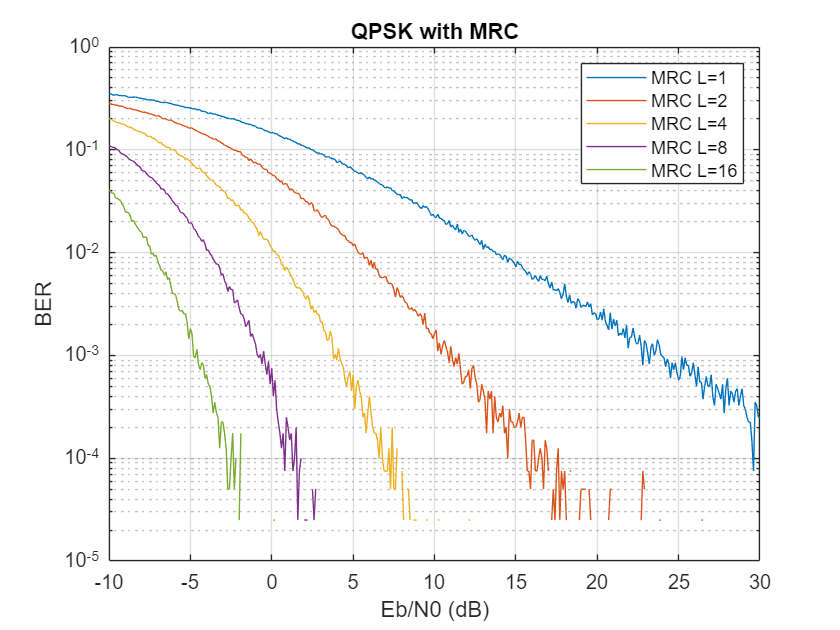


L_list     = [1,2,4,8,16];
EbN0_dB    = -10:0.1:30;
Nsym       = 20000;

ber_mrc    = zeros(length(L_list), numel(EbN0_dB));
ber_sc     = zeros(length(L_list), numel(EbN0_dB));
ber_egc    = zeros(length(L_list), numel(EbN0_dB));

for i_L = 1:length(L_list)
    L = L_list(i_L);
    for i_snr = 1:numel(EbN0_dB)
        EbN0 = 10^(EbN0_dB(i_snr)/10);
        N0   = 1/EbN0;


        bits = randi([0,1], Nsym, 2);
        x    = (2*bits(:,1)-1) + 1j*(2*bits(:,2)-1);
        h = (randn(Nsym,L) + 1j*randn(Nsym,L))/sqrt(2);
        n = (randn(Nsym,L) + 1j*randn(Nsym,L))*sqrt(N0/2);
        y = h .* x + n;          
        y_mrc = sum(conj(h).*y, 2);
        bits_hat = [real(y_mrc)>0, imag(y_mrc)>0];
        ber_mrc(i_L,i_snr) = mean(bits_hat~=bits,'all');

        [~, idx] = max(abs(h).^2, [], 2);
        ind      = sub2ind([Nsym, L], (1:Nsym)', idx);
        y_sc     = y(ind);
        bits_hat = [real(y_sc)>0, imag(y_sc)>0];
        ber_sc(i_L,i_snr) = mean(bits_hat~=bits,'all');


        y_egc = sum(y .* exp(-1j*angle(h)), 2);
        bits_hat = [real(y_egc)>0, imag(y_egc)>0];
        ber_egc(i_L,i_snr) = mean(bits_hat~=bits,'all');
    end
end


figure;
for i=1:length(L_list)
    semilogy(EbN0_dB, ber_mrc(i,:), '-','DisplayName',sprintf('MRC L=%d',L_list(i)));
    hold on;
end
grid on; xlabel('Eb/N0 (dB)'); ylabel('BER');
title('QPSK with MRC'); legend;

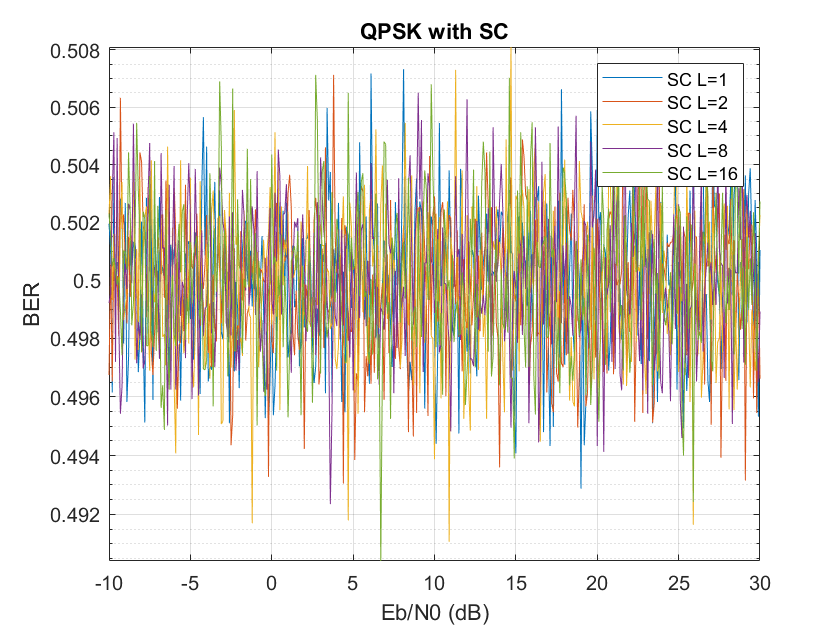


figure;
for i=1:length(L_list)
    semilogy(EbN0_dB, ber_sc(i,:), '-','DisplayName',sprintf('SC L=%d',L_list(i)));
    hold on;
end
grid on; xlabel('Eb/N0 (dB)'); ylabel('BER');
title('QPSK with SC'); legend;

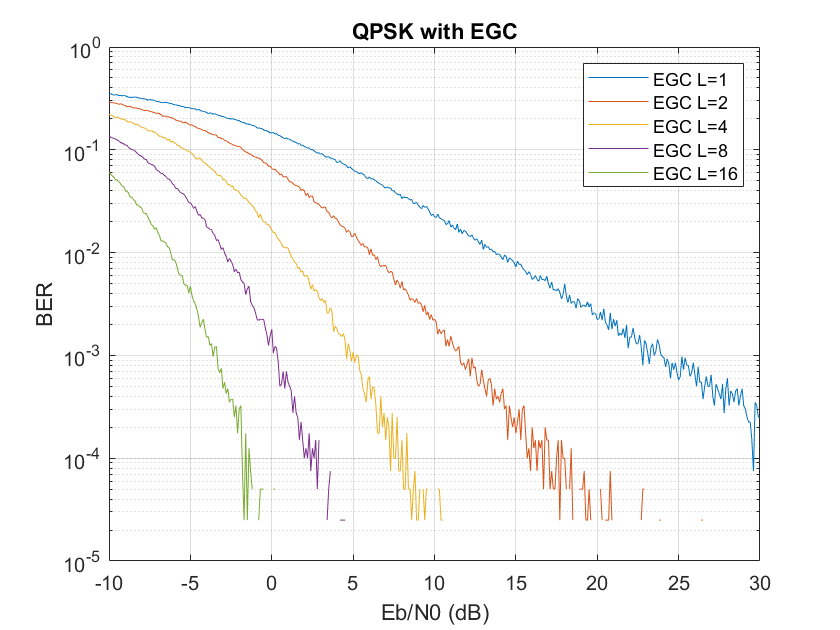


figure;
for i=1:length(L_list)
    semilogy(EbN0_dB, ber_egc(i,:), '-','DisplayName',sprintf('EGC L=%d',L_list(i)));
    hold on;
end
grid on; xlabel('Eb/N0 (dB)'); ylabel('BER');
title('QPSK with EGC'); legend;

## Q2

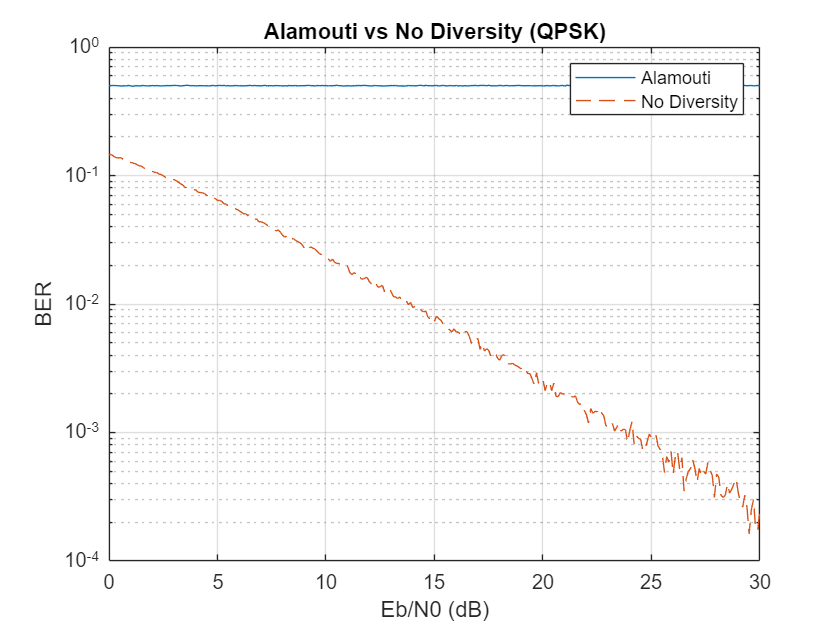

EbN0_dB2    = 0:0.1:30;
ber_alam_q  = zeros(1,numel(EbN0_dB2));
ber_no_q    = zeros(1,numel(EbN0_dB2));

for i_snr = 1:numel(EbN0_dB2)
    EbN0 = 10^(EbN0_dB2(i_snr)/10);
    N0   = 1/EbN0;

    bits = randi([0,1], 2*Nsym, 2);
    s    = (2*bits(:,1)-1) + 1j*(2*bits(:,2)-1);

    s1 = s(1:2:end);  s2 = s(2:2:end);
    h1 = (randn(Nsym,1)+1j*randn(Nsym,1))/sqrt(2);
    h2 = (randn(Nsym,1)+1j*randn(Nsym,1))/sqrt(2);
    n1 = (randn(Nsym,1)+1j*randn(Nsym,1))*sqrt(N0/2);
    n2 = (randn(Nsym,1)+1j*randn(Nsym,1))*sqrt(N0/2);

    r1 = h1.*(s1/sqrt(2)) + h2.*(s2/sqrt(2)) + n1;
    r2 = h1.*(-conj(s2)/sqrt(2)) + h2.*( conj(s1)/sqrt(2)) + n2;

    s1_hat = conj(h1).*r1 + h2.*conj(r2);
    s2_hat = conj(h2).*r1 - h1.*conj(r2);
    bits_hat1 = [real(s1_hat)>0, imag(s1_hat)>0];
    bits_hat2 = [real(s2_hat)>0, imag(s2_hat)>0];
    bits_hat  = [bits_hat1; bits_hat2];
    ber_alam_q(i_snr) = mean(bits_hat~=bits,'all');

    h  = (randn(2*Nsym,1)+1j*randn(2*Nsym,1))/sqrt(2);
    n  = (randn(2*Nsym,1)+1j*randn(2*Nsym,1))*sqrt(N0/2);
    y  = h .* s + n;
    sh = conj(h).*y;
    bits_hat = [real(sh)>0, imag(sh)>0];
    ber_no_q(i_snr) = mean(bits_hat~=bits,'all');
end

figure;
semilogy(EbN0_dB2, ber_alam_q, '-', EbN0_dB2, ber_no_q, '--');
grid on; xlabel('Eb/N0 (dB)'); ylabel('BER');
title('Alamouti vs No Diversity (QPSK)'); legend('Alamouti','No Diversity');

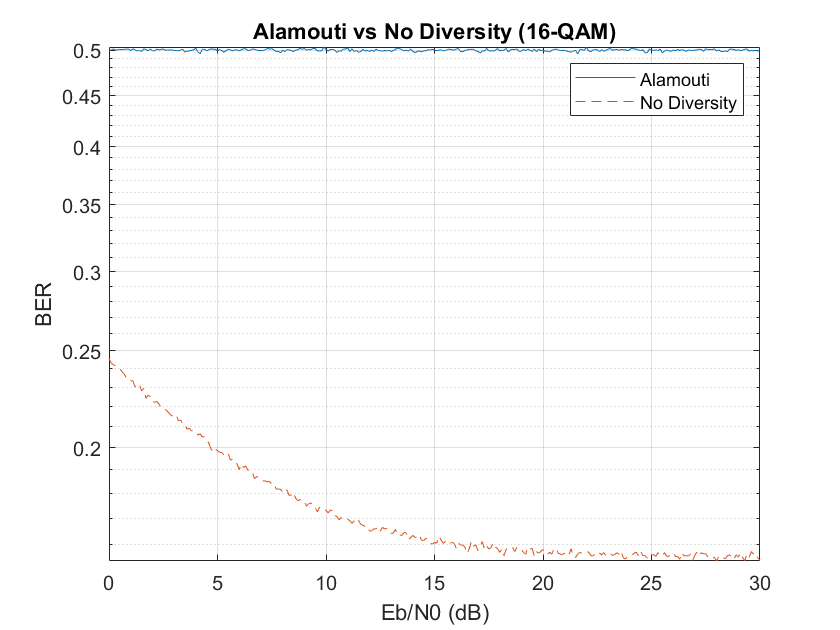


%--- 16-QAM ---% 
scale = sqrt(4/10);
ber_alam_16 = zeros(1,numel(EbN0_dB2));
ber_no_16   = zeros(1,numel(EbN0_dB2));

for i_snr = 1:numel(EbN0_dB2)
    EbN0 = 10^(EbN0_dB2(i_snr)/10);
    N0   = 1/EbN0;

    bits = randi([0,1], 2*Nsym, 4);
    a = (2*bits(:,1)-1) .* (2*(1-bits(:,2)) + 1);
    b = (2*bits(:,3)-1) .* (2*(1-bits(:,4)) + 1);
    s = (a + 1j*b)*scale;

    s1 = s(1:2:end);  s2 = s(2:2:end);
    h1 = (randn(Nsym,1)+1j*randn(Nsym,1))/sqrt(2);
    h2 = (randn(Nsym,1)+1j*randn(Nsym,1))/sqrt(2);
    n1 = (randn(Nsym,1)+1j*randn(Nsym,1))*sqrt(N0/2);
    n2 = (randn(Nsym,1)+1j*randn(Nsym,1))*sqrt(N0/2);

    r1 = h1.*(s1/sqrt(2)) + h2.*(s2/sqrt(2)) + n1;
    r2 = h1.*(-conj(s2)/sqrt(2)) + h2.*( conj(s1)/sqrt(2)) + n2;

    s1_hat = conj(h1).*r1 + h2.*conj(r2);
    s2_hat = conj(h2).*r1 - h1.*conj(r2);
    detect = @(z) [ real(z)>0, abs(real(z))<2*scale, imag(z)>0, abs(imag(z))<2*scale ];
    bh1 = detect(s1_hat);
    bh2 = detect(s2_hat);
    bh  = [bh1; bh2];
    ber_alam_16(i_snr) = mean(bh~=bits,'all');

    h  = (randn(2*Nsym,1)+1j*randn(2*Nsym,1))/sqrt(2);
    n  = (randn(2*Nsym,1)+1j*randn(2*Nsym,1))*sqrt(N0/2);
    y  = h .* s + n;
    sh = conj(h).*y;
    bh  = detect(sh);
    ber_no_16(i_snr) = mean(bh~=bits,'all');
end

figure;
semilogy(EbN0_dB2, ber_alam_16, '-', EbN0_dB2, ber_no_16, '--');
grid on; xlabel('Eb/N0 (dB)'); ylabel('BER');
title('Alamouti vs No Diversity (16-QAM)'); legend('Alamouti','No Diversity');